## MODI OMKAR

### **19EE30018**

### **Session 3: Model representation and time-domain analysis**

**1A)**

**The time constant of circuit**  = **L/R **= 10*10^(-3)/10 = **10^(-3) s**

Simulation run time chosen = **1 seconds**

ODE equation :-  **V- L*(dI/dt) = I*R**

V= 1 volt, L = 0.01 H, R = 10 ohms

substituting the values we get the final equation as,

**dI/dt + 1000*I -100 = 0**

Solution :-** I(t) = V(1-exp(-Rt/L)) = 0.1*(1-exp(-1000t))**

The simulation starts with 0.1 volt itself because as simulation starts at 0s the step voltage at the instant is 1 and unable to have memory of 0- sec.

To solve this change the simulation time to 0- (-0.000001s) so that we get correct output.

**Current waveform is as follows**

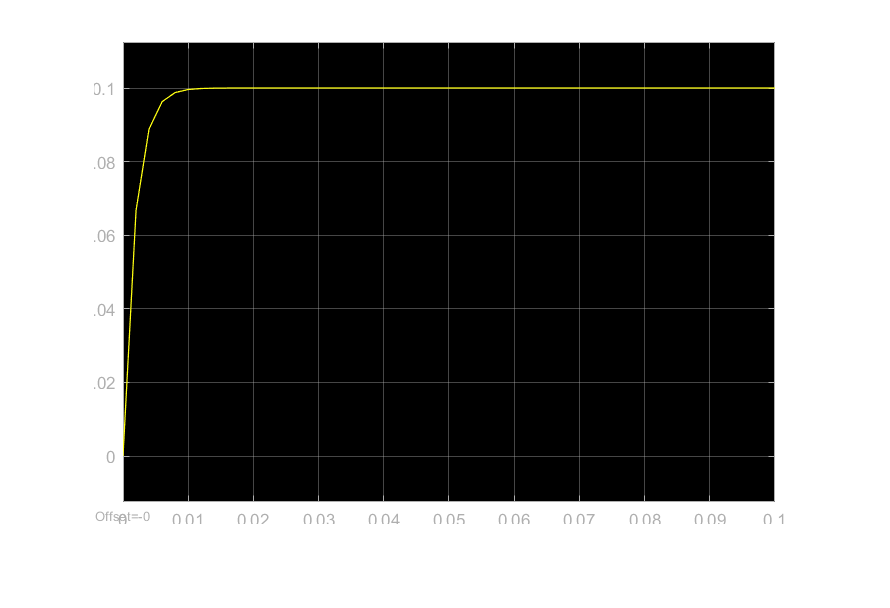

imshow(imread("1a.png"))

**Voltage waveform is as follows**

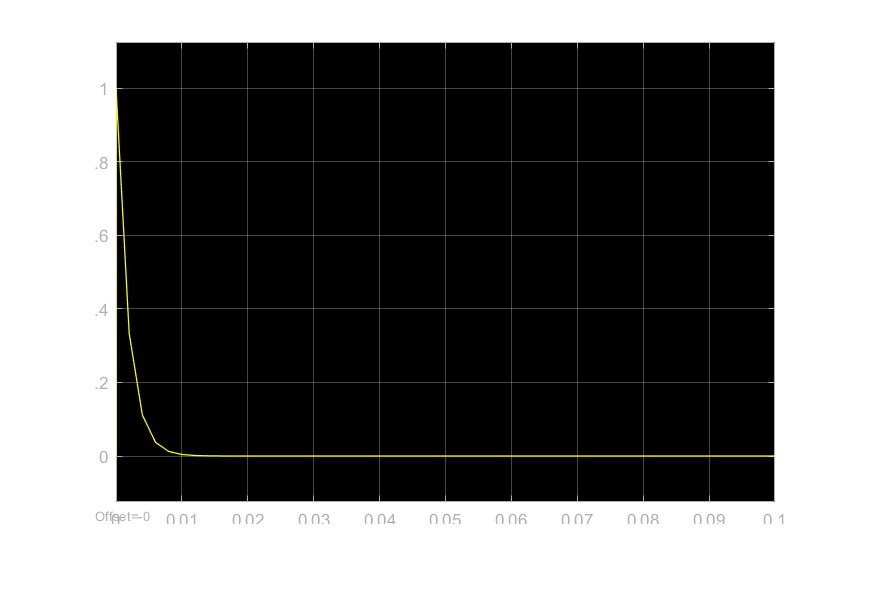

imshow(imread("1a voltage.png"))

**1B i)**

G(s) = (s+1)/(s)(s+2)(s+3)

        = (s+1)/s^3 + 5*s^2 + 6s

num = [1 1];
den = [1 5 6 0];
tf_method = tf(num,den)

tf_method =
 
        s + 1
  -----------------
  s^3 + 5 s^2 + 6 s
 
Continuous-time transfer function.




zeros = [-1];
poles = [0 -2 -3];
gain = 1;
zpk_method = zpk(zeros,poles,gain)

zpk_method =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



**ii)**

G(s) = -s-1 / s^2 + 5*s + 6

        =  -1*(s+1)/(s+2)(s+3)

num = [-1,-1];
den = [1,5,6];
tf_method = tf(num,den)

tf_method =
 
     -s - 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.




zeros = [-1];
poles = [-2 -3];
gain = -1;
zpk_method = zpk(zeros,poles,gain)

zpk_method =
 
    - (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



**1C**

**i)**

G(s) = (s+1)/(s)(s+2)(s+3)

b = [0 0 1 1];
a = [1 5 6 0];

[A,B,C,D] = tf2ss(b,a)

A =     -5    -6     0
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     1     1


D = 0

**ii)**

G(s) = -s-1 / s^2 + 5*s + 6

b = [0 -1 -1];
a = [1 5 6];

[A,B,C,D] = tf2ss(b,a)

A =     -5    -6
     1     0


B =      1
     0


C =     -1    -1


D = 0

**2)**

m1 = 1;
k1 = 1;
b1 = 0.1;
m2 = 2;
k2 = 1.5;
b2 = 0.2;

**equation of motions :-**

for mass 1

**Fa - b1x1' - k1(x1-x2) = m1x1"**

for mass 2

**k1(x1-x2) - b2x2' - k2x2 = m2x2"**

representing them in state space form

A = [[0 0 1 0]; [0 0 0 1]; [-k1/m1 k1/m1 -b1/m1 0]; [k1/m2 -(k1+k2)/m2 0 -b2/m2]];
B = [0;0;1/m1;0];
C = [0 1 0 0];
D = [0];

[num,den] = ss2tf(A,B,C,D)

num =          0         0         0         0    0.5000


den =     1.0000    0.2000    2.2600    0.2250    0.7500


transfer_function = tf(num, den)

transfer_function =
 
                     0.5
  -----------------------------------------
  s^4 + 0.2 s^3 + 2.26 s^2 + 0.225 s + 0.75
 
Continuous-time transfer function.



**unit impulse response**

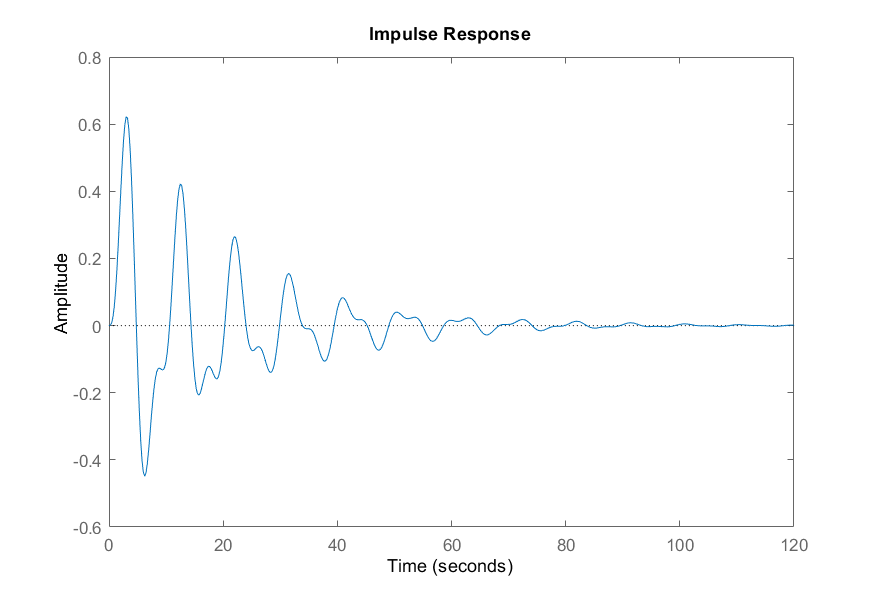

impulse(transfer_function)

**unit step response**

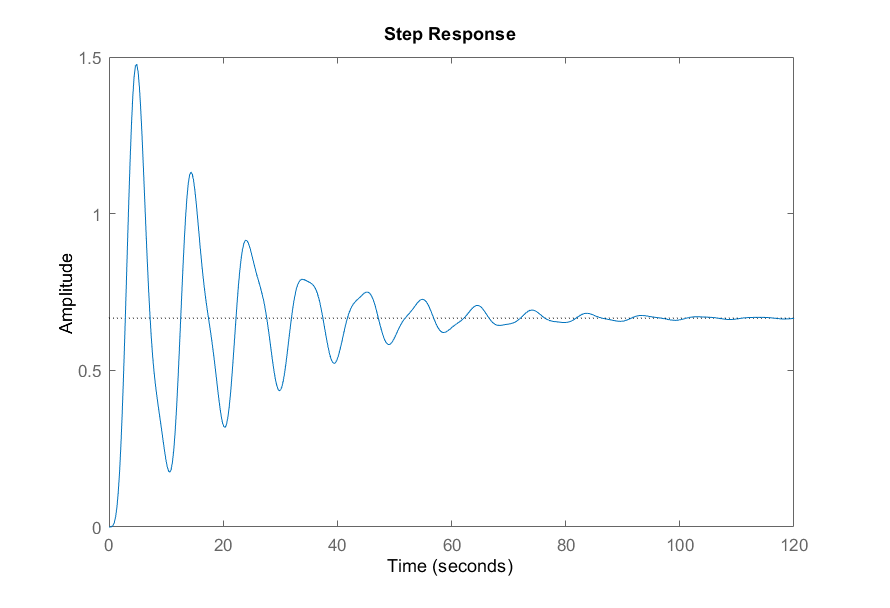

step(transfer_function)

**sine response**

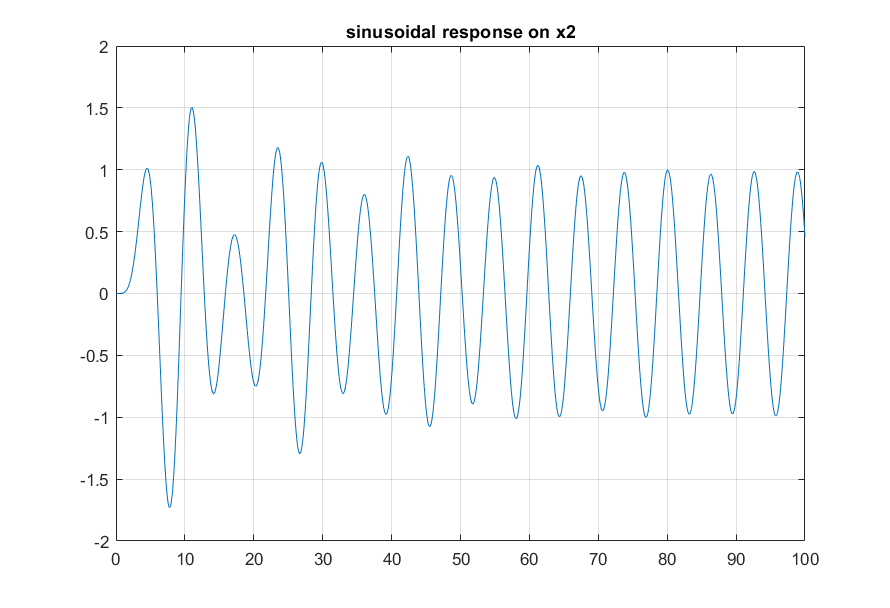

t = linspace(0,100,10000);
u = sin(t);
y = lsim(transfer_function,u,t);
plot(t,y);
grid on
title("sinusoidal response on x2");

**Simulink generated plots**

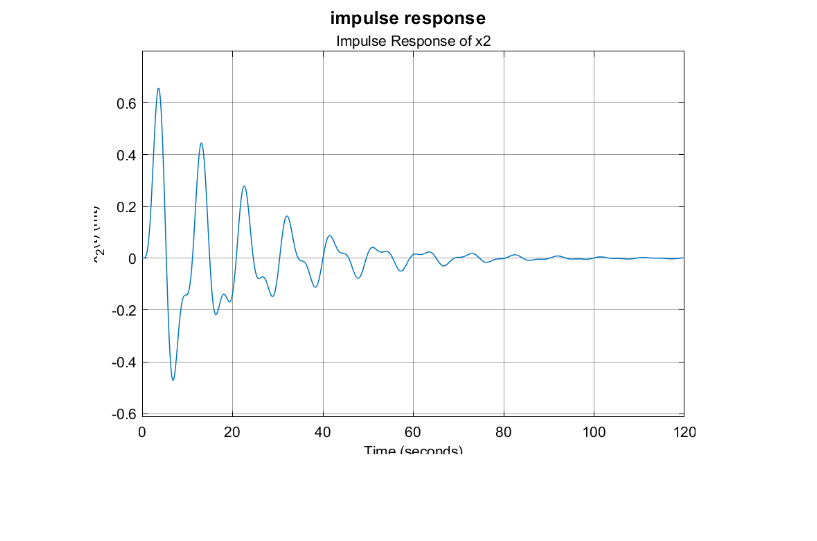

imshow(imread("q2 impulse response simulink.png"))
title("impulse response");

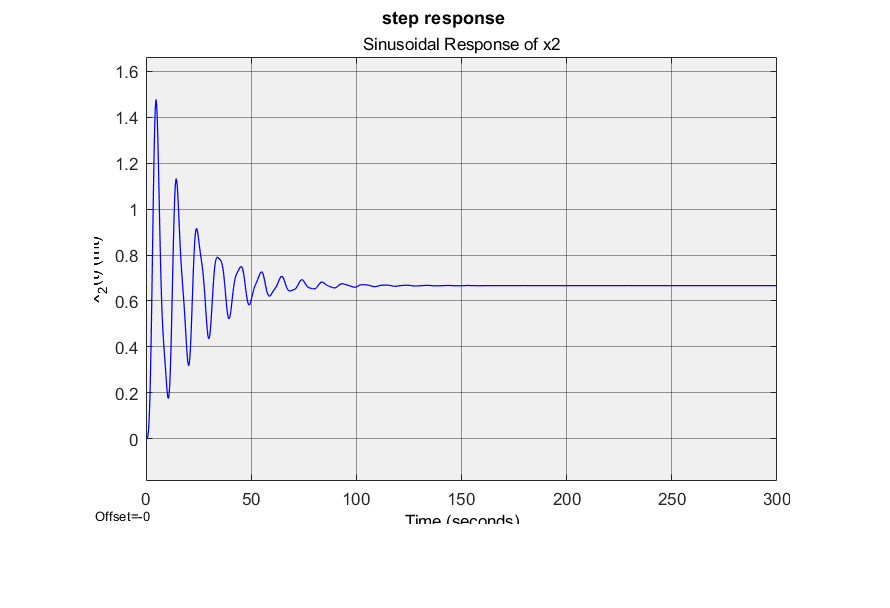

imshow(imread("q2 step response simulink.png"))
title("step response");

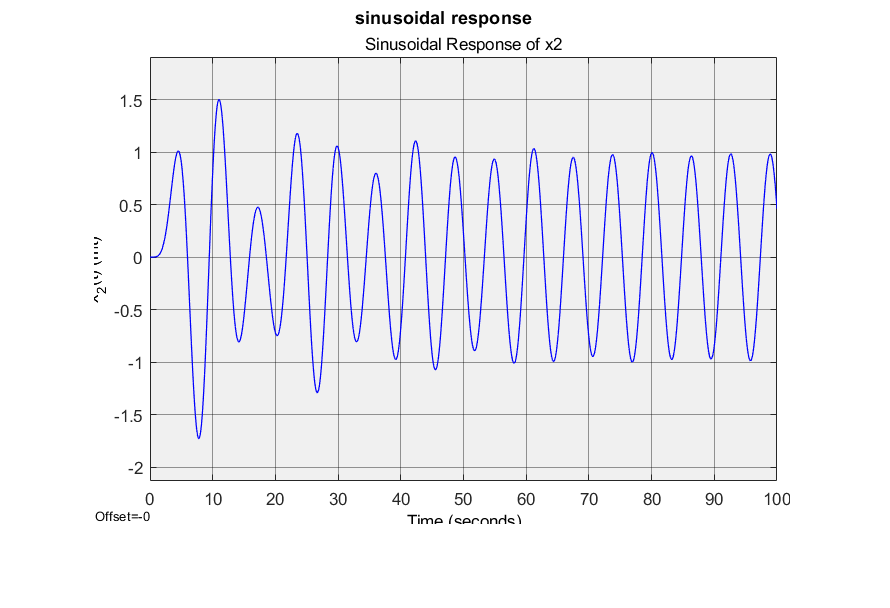

imshow(imread("q2 fvsx2 simulink.png"))
title("sinusoidal response");

It is verified that simulink generated waveform and tf generated are same.

**3A)**

It is Underdamped form. It is second order system. 

This can also represent a system having one zero. because there is overshoot observed

for example let the general transfer function be

G(s) = w^2/(s^2 + 2dws + w^2) 

taking w = 1

and d= 0.7

G(s) = 1/s^2+1.4s+1

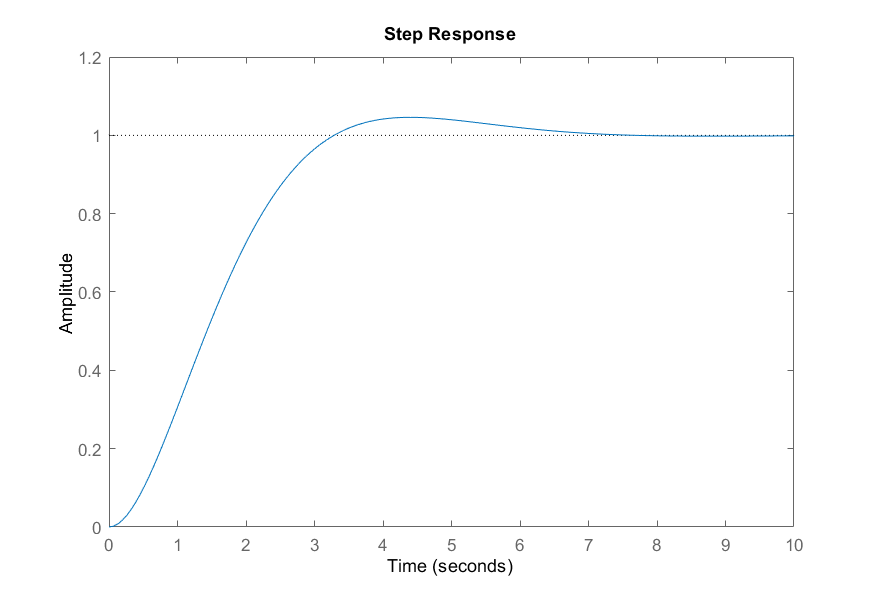

ex = tf([1],[1 1.4 1]);
step(ex)

Real life example can be of guitar strings. where the amplitude of output response decays exponentially over time

**3B)**

Yes, we can observe overshoot in over-damped 2nd order system, if the system has **a negative zero** which amplifies the initial response and may cause an overshoot.

for example,

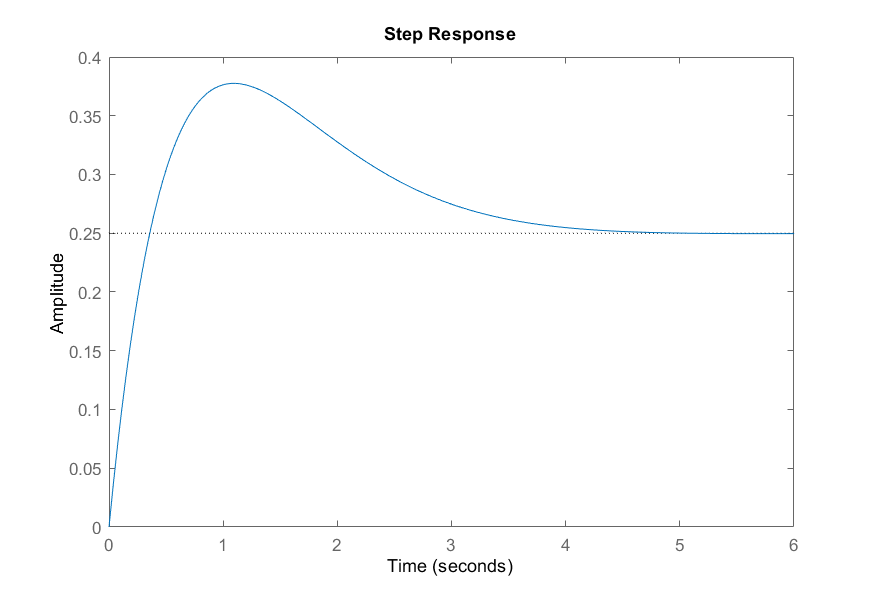

step([1,0.5],[1,2.5,2])

**4)**

**a)**

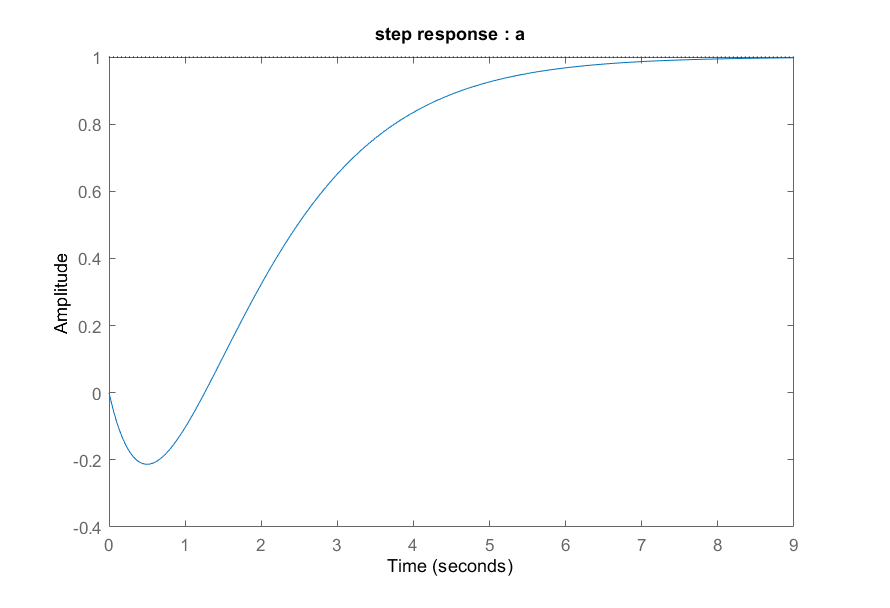

a = tf([-1 1],[1 2 1]);
step(a)
title('step response : a')

zero(a)

ans = 1

zero(a-1)

ans =      0
    -3


It is **strictly prope**r function.

zeros of transfer functions is **s = 1**.

G(0) = 1

G(inf) = 0

number of positive zeros of G(s) is** 1** (**s = 1)**.{1}

number of positive zeros of G(s)-G(0) is** 0** . {0,-3}

number of positive zeros of G(s)-G(inf) is** 1** (**s = 1)**. {1}

- Strictly proper

- Initial  undershoot

- zero crossing

- **no** overshoot

- 1 positive zero of $G(s)$

- 0 positive zero of $G(s)-G(0)$

- 1 positive zero of $G(s)-G(\infty)$

**b)**

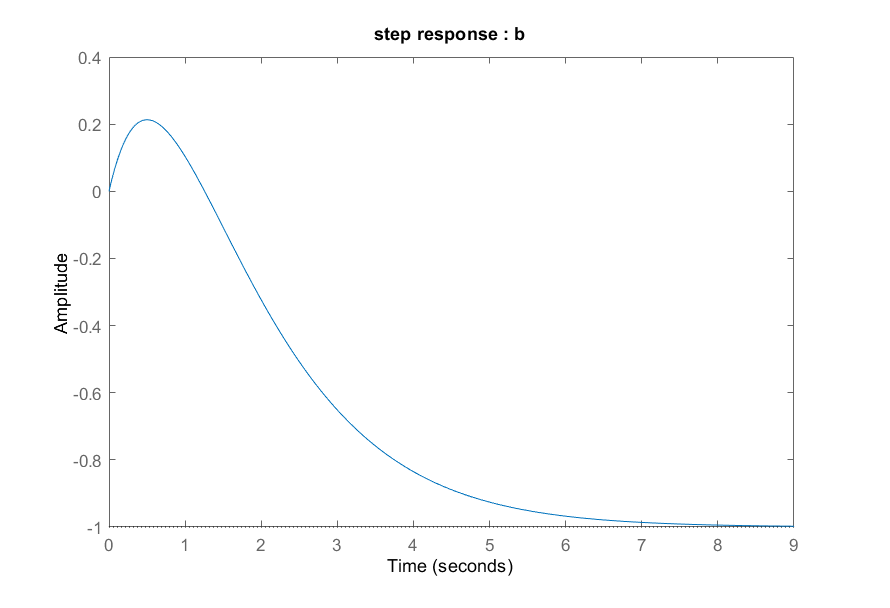

b = tf([1 -1],[1 2 1]);
step(b)
title('step response : b')

zero(b)

ans = 1

zero(b+1)

ans =      0
    -3


It is **strictly proper** function.

zeros of transfer functions is **s = 1**.

G(0) =  -1

G(inf) =  0

number of positive zeros of G(s) is** 1** (**s = 1)**.{1}

number of positive zeros of G(s)-G(0) is** 0**. {0,-3}

number of positive zeros of G(s)-G(inf) is** 1** (**s = 1)**. {1}

- Strictly proper

- Initial undershoot for(negative steady state)

- zero crossing

- overshoot

- 1 positive zero of $G(s)$

- 1 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

**c)**

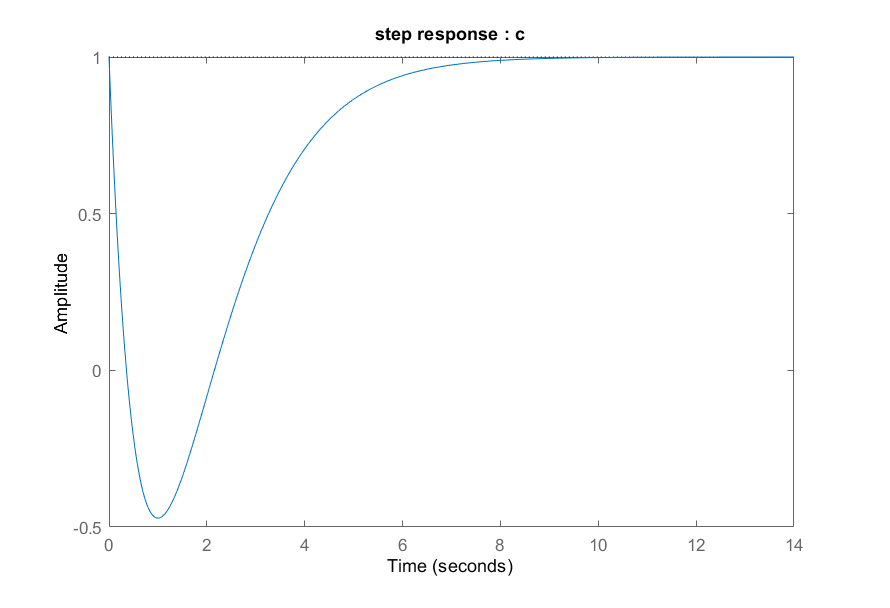

c = tf([1 -2 1],[1 2 1]);
step(c)
title('step response : c')

zero(c)

ans =      1
     1


zero(c-1)

ans = 0

It is **proper** function.

zeros of transfer functions are **s = 1,1.**

G(0) = 1

G(inf) = 1

number of positive zeros of G(s) is** 2** (**s = 1,s=1)**.{1,1}

number of positive zeros of G(s)-G(0) is** 0**. {0}

number of positive zeros of G(s)-G(inf) is** 0** . {0}

- Proper

- Initial undershoot

- zero crossing

- **no **overshoot

- 2 positive zeros of $G(s)$

- 0 positive zero of $G(s)-G(\infty)$

- 0 positive zero of $G(s)-G(0)$

**d)**

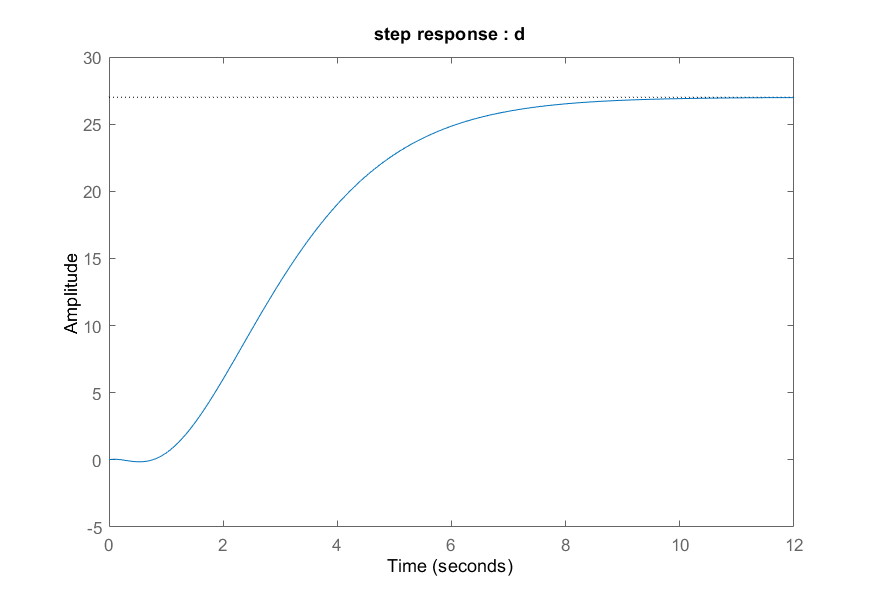

d = tf([1 -10 27], [1 3 3 1]);
step(d)
title('step response : d')

zero(d)

ans =    5.0000 + 1.4142i
   5.0000 - 1.4142i


zero(d-1)

ans =   -1.7229 + 3.8748i
  -1.7229 - 3.8748i
   1.4459 + 0.0000i


It is** strictly proper **function.

zeros of transfer functions are **s = 5 + i1.4142** and **s = 5 - i1.4142**

G(0) = 1

G(inf) = 0

number of positive zeros of G(s) is** 0 **

number of positive zeros of G(s)-G(0) is** 1 (s=1.4459)**. {1.4459}

number of positive zeros of G(s)-G(inf) is** 0** .

- Strictly proper

- **no **Initial undershoot

- zero crossing

- **no** overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 1 positive zero of $G(s)-G(0)$, 2 complex zeros

**e)**

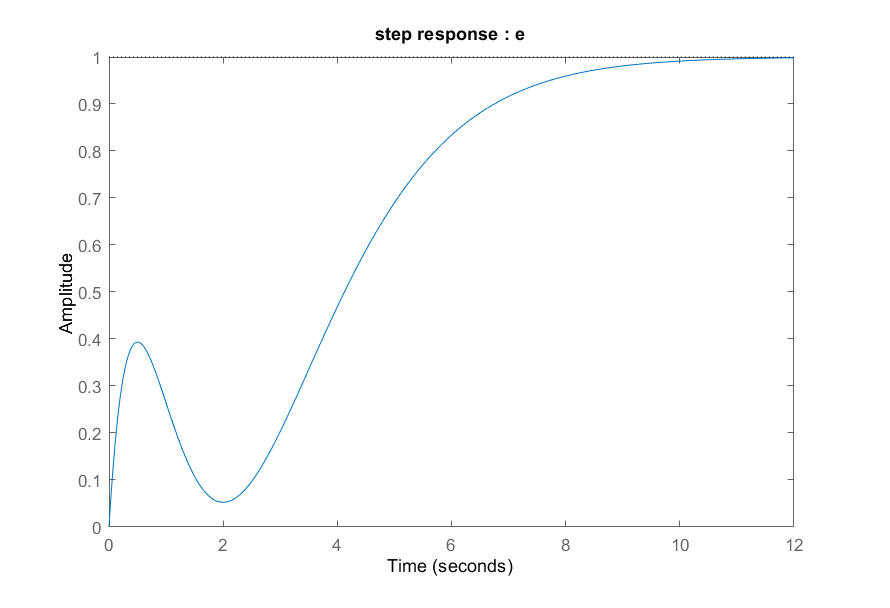

e = tf([2 -1 1],[1 3 3 1]);
step(e)
title('step response : e')

zero(e)

ans =    0.2500 + 0.6614i
   0.2500 - 0.6614i


zero(e-1)

ans =    0.0000 + 0.0000i
  -0.5000 + 1.9365i
  -0.5000 - 1.9365i


It is **strictly proper** function.

zeros of transfer functions are** s = 0.25 + i0.6614** and **s = 0.25 -i0.6614**

G(0) = 1

G(inf) = 0

number of positive zeros of G(s) is** 0 .**

number of positive zeros of G(s)-G(0) is** 0.**

number of positive zeros of G(s)-G(inf) is** 0** .

- Strictly proper

- **no** Initial undershoot

- **no **zero crossing

- **no **overshoot

- 0 positive zero of $G(s)$,2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$,2 complex zeros

**f)**

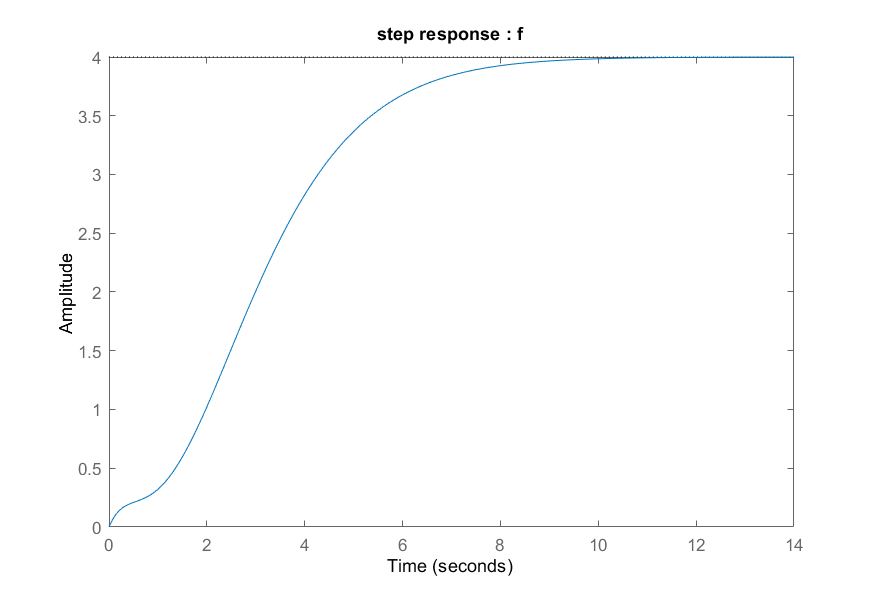

f = tf([1 -1 4],[1 3 3 1]);
step(f)
title('step response : f')

zero(f)

ans =    0.5000 + 1.9365i
   0.5000 - 1.9365i


zero(f-4)

ans =    0.0000 + 0.0000i
  -1.3750 + 1.1659i
  -1.3750 - 1.1659i


It is **strictly proper** function.

zeros of transfer functions are **s = 0.5 + i1.9365** and **s = 0.5 -i1.9365**

G(0) = 4

G(inf) = 0

number of positive zeros of G(s) is** 0 .**

number of positive zeros of G(s)-G(0) is** 0.**

number of positive zeros of G(s)-G(inf) is** 0** .

- Strictly proper

- **no **initial undershoot

- **no** zero crossing

- **no **overshoot

- 0 positive zero of $G(s)$, 2 complex zeros

- 0 positive zero of $G(s)-G(\infty)$,2 complex zeros

- 0 positive zero of $G(s)-G(0)$,2 complex zeros

T = readtable("question 4 table.xlsx",'Format','auto')

T = 7×7 table
                Var1                        Q3a                    Q3b               Q3c                Q3d                    Q3e                    Q3f        
    ____________________________    ___________________    ___________________    __________    ___________________    ___________________    ___________________

    {'Properness'              }    {'Strictly proper'}    {'Strictly proper'}    {'proper'}    {'Strictly proper'}    {'Strictly proper'}    {'Strictly proper'}
    {'+ve zeros of G(s)'       }    {'1'              }    {'1'              }    {'2'     }    {'0'              }    {'0'              }    {'0'              }
    {'+ve zeros of G(s)-G(0)'  }    {'0'              }    {'0'              }    {'0'     }    {'1

4)

B) when input is ramp function (unbounded input) and is feedback loop we get bounded ouput for example this is because at origin itself there exist a zero so no response will be observed at that point and we cannot change the state whatever input is provided.

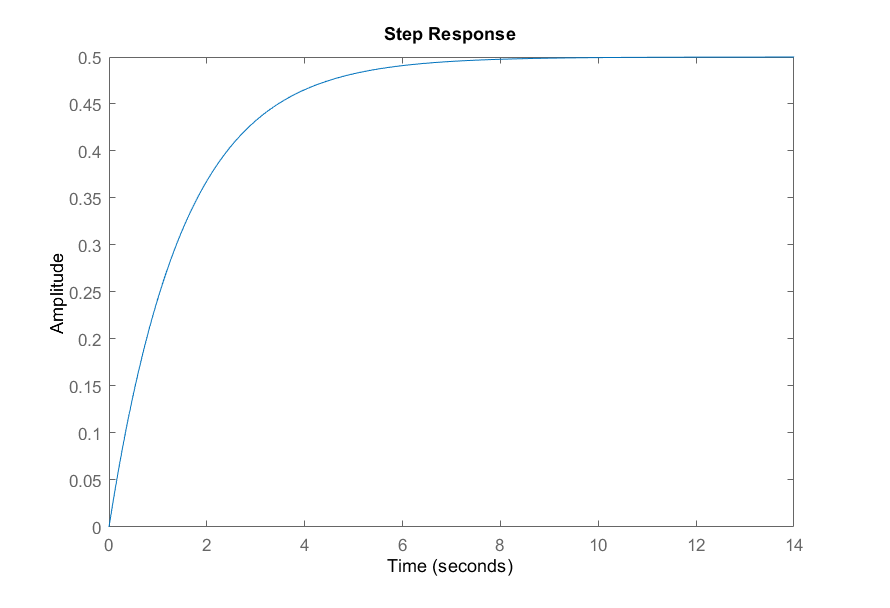

s = tf('s');
G = tf([1 0],[1,2]);
k = 2;
step(feedback(G,k)/s)

**5)**

**A)**

d = 0.2

d = 0.2000

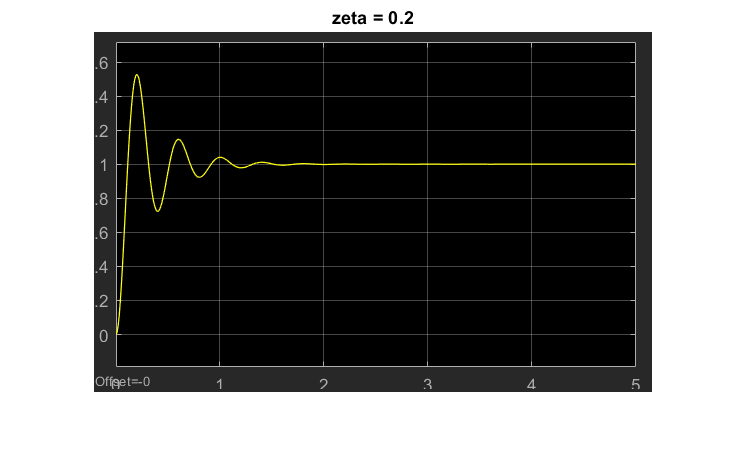

imshow(imread("q5 0.2.png"))
title("zeta = 0.2");

d = 0.4

d = 0.4000

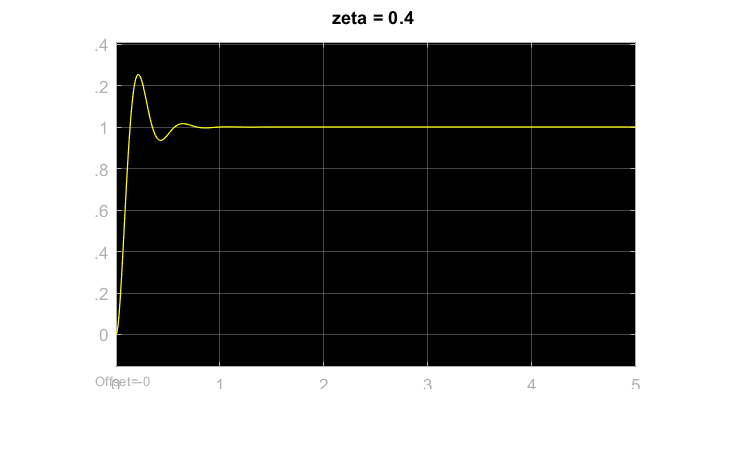

imshow(imread("q5 0.4.png"))
title("zeta = 0.4");

d = 0.6

d = 0.6000

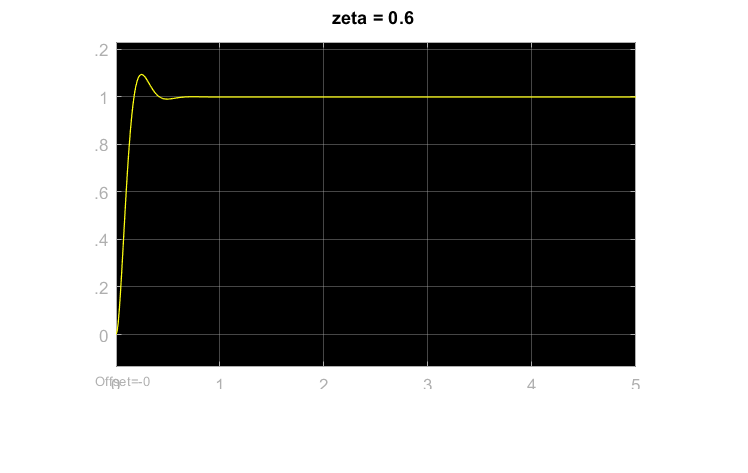

imshow(imread("q5 0.6.png"))
title("zeta = 0.6");

d = 0.8

d = 0.8000

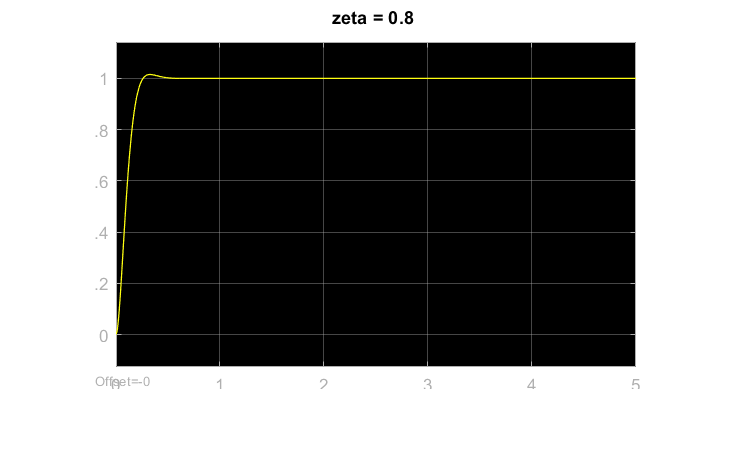

imshow(imread("q5 0.8.png"))
title("zeta = 0.8");

d = 1

d = 1

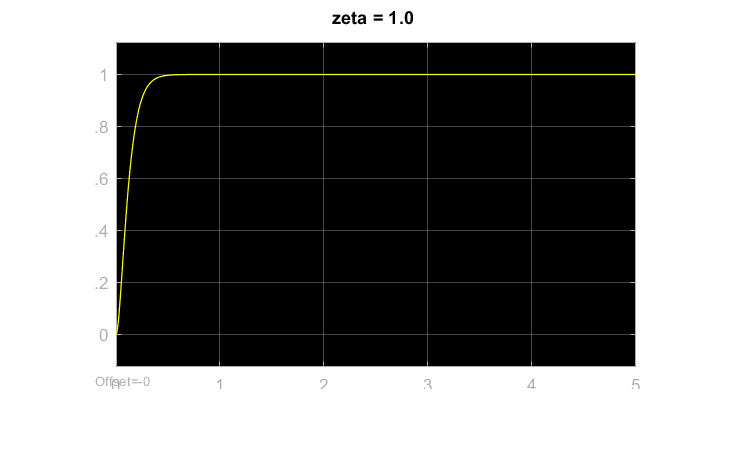

imshow(imread("q5 1.0.png"))
title("zeta = 1.0");

d = 1.2

d = 1.2000

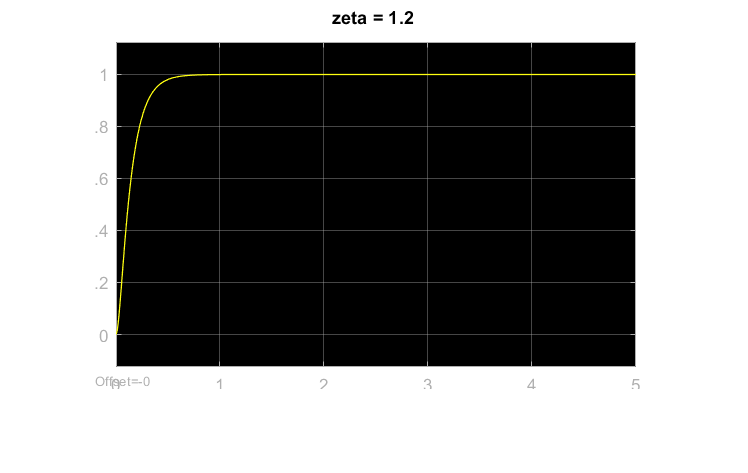

imshow(imread("q5 1.2.png"))
title("zeta = 1.2");

d = 1.5

d = 1.5000

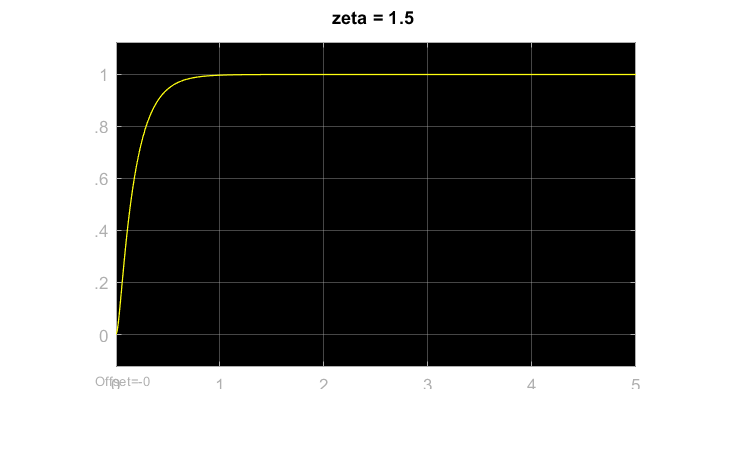

imshow(imread("q5 1.5.png"))
title("zeta = 1.5");

**B)**

**zeta = 0.6;**

**natural frequency  = wn;**

**th = atan(sqrt(1-zeta^2)/zeta);**

**wd = wn*(sqrt(1-zeta^2));**

**rise_time = (pi - th)/wd**

**peak_time = pi/wd**

**max_peak_overshoot = exp(-pi*zeta/sqrt(1-zeta^2))**

**settling_time = 4/(zeta*wn)**

wd can be calculated by timeperiod of 2 successive waveforms.